# Just some useful Signal Processing things for Modal Analysis

`Bradley Horton: bhorton@mathworks.com`

## Some Common data used in this script

Clear your workspace

clear

Let's setup a sampling experiment

gdsp_basic.Fs_hz        = 2e3;  % (Hz)
gdsp_basic.dt           = 1/gdsp_basic.Fs_hz;  % (secs)
gdsp_basic.block_size_N = 65536;    % NOTE: 2^13 == 65536
gdsp_basic.time_block_T = gdsp_basic.block_size_N * gdsp_basic.dt;  % (secs)
gdsp_basic.df_hz        = 1/gdsp_basic.time_block_T;  % (Hz)
gdsp_basic.nyq_hz       = gdsp_basic.Fs_hz / 2;  % (Hz)
gdsp_basic.nyq_ind      = 1 + (gdsp_basic.block_size_N/2);

gdsp_basic

gdsp_basic = struct with fields:
           Fs_hz: 2000
              dt: 5.0000e-04
    block_size_N: 65536
    time_block_T: 32.7680
           df_hz: 0.0305
          nyq_hz: 1000
         nyq_ind: 32769


Define a time array

t_col    = gdsp_basic.dt    * [0:(gdsp_basic.block_size_N - 1)]' ;

f_hz_col = gdsp_basic.df_hz * [0:(gdsp_basic.block_size_N - 1)]' ;

whos 

  Name                Size             Bytes  Class     Attributes

  f_hz_col        65536x1             524288  double              
  gdsp_basic          1x1                961  struct              
  t_col           65536x1             524288  double              



## PART_01:  Bandwidth of Impulse type excitation

Define the width of the impulse

width_in_samples   =  10;
width_in_seconds   = gdsp_basic.dt * width_in_samples

width_in_seconds = 0.0050

width_bandwidth_Hz = 1/width_in_seconds

width_bandwidth_Hz = 200

Specify the UNIT magnitude impulse

y_imp         = zeros( size(t_col) );

y_imp(1:(width_in_samples)) = 1;

### Plot the Impulse signal:

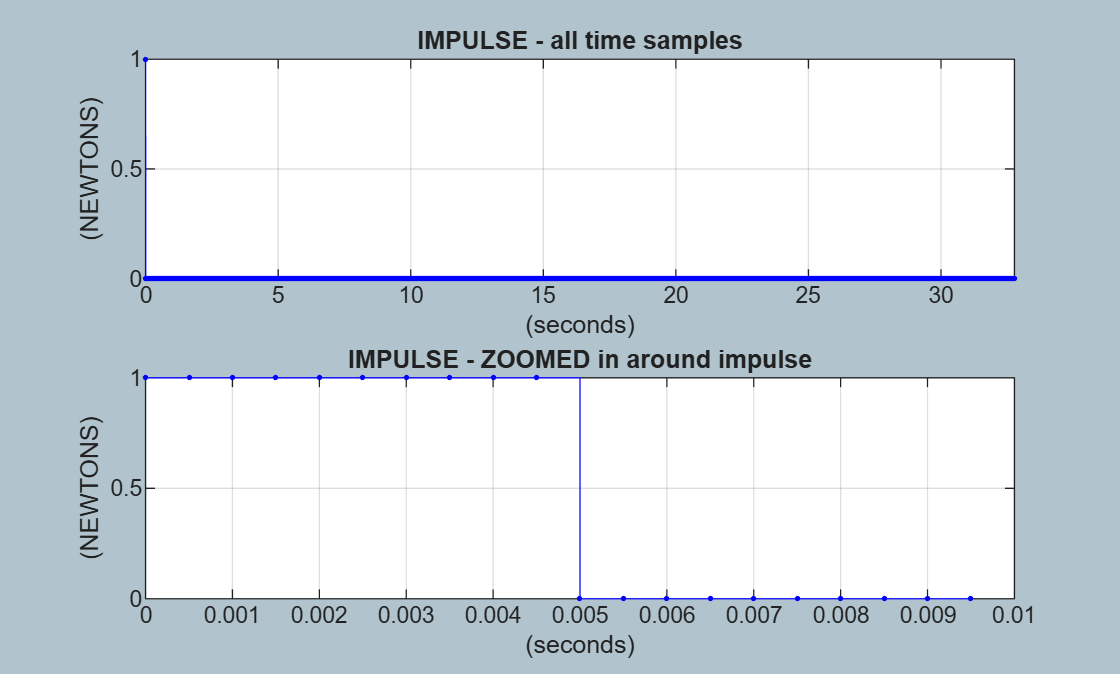

figure;
    subplot(2,1,1);
        stairs(t_col, y_imp, "-b.");
            grid on
            xlabel("(seconds)"); ylabel("(NEWTONS)");
            title("IMPULSE - all time samples")
            axis tight
    subplot(2,1,2);
        stairs(t_col(1:(2*width_in_samples)), y_imp(1:(2*width_in_samples)), "-b.");
            grid on
            xlabel("(seconds)"); ylabel("(NEWTONS)")  
            title("IMPULSE - ZOOMED in around impulse")

### Compute the FFT

yfft            = fft(y_imp);

yfft_dB         = 20*log10( abs(yfft)  );

DC_gain_dB      = yfft_dB(1);

Look for the $3\;\mathrm{dB}$ drop from the DC gain

tmp_ind             = find((yfft_dB) < (DC_gain_dB-3) );
ind_of_3dB_drop     = tmp_ind(1);
freq_hz_at_3dB_drop = f_hz_col(ind_of_3dB_drop);
fprintf("\n Frquency at 3dB drop --->  %.2f", freq_hz_at_3dB_drop)


 Frquency at 3dB drop --->  88.84

### Plot the FFT spectrum:

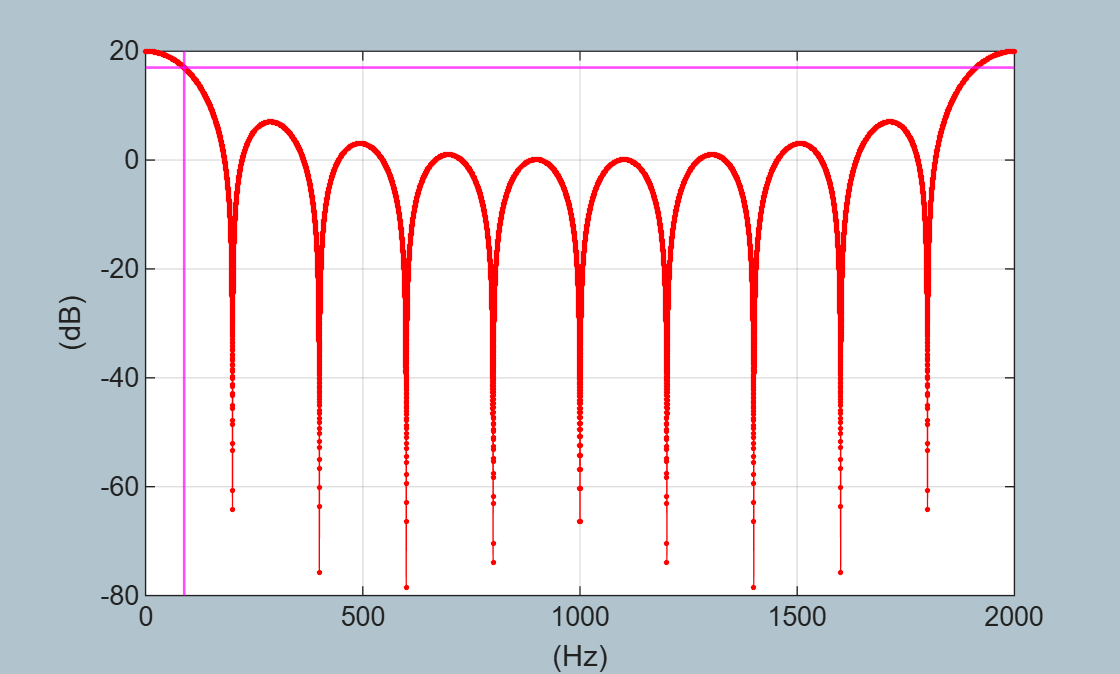

figure;
    plot(f_hz_col, 20*log10(abs(yfft)), "-r.");
        grid on
        xlabel("(Hz)"); ylabel("(dB)")
    hold on
        yline((DC_gain_dB - 3),    "-m", "LineWidth",1)
        xline(freq_hz_at_3dB_drop, "-m", "LineWidth",1)

### Plot The Power Spectral Density (PSD)

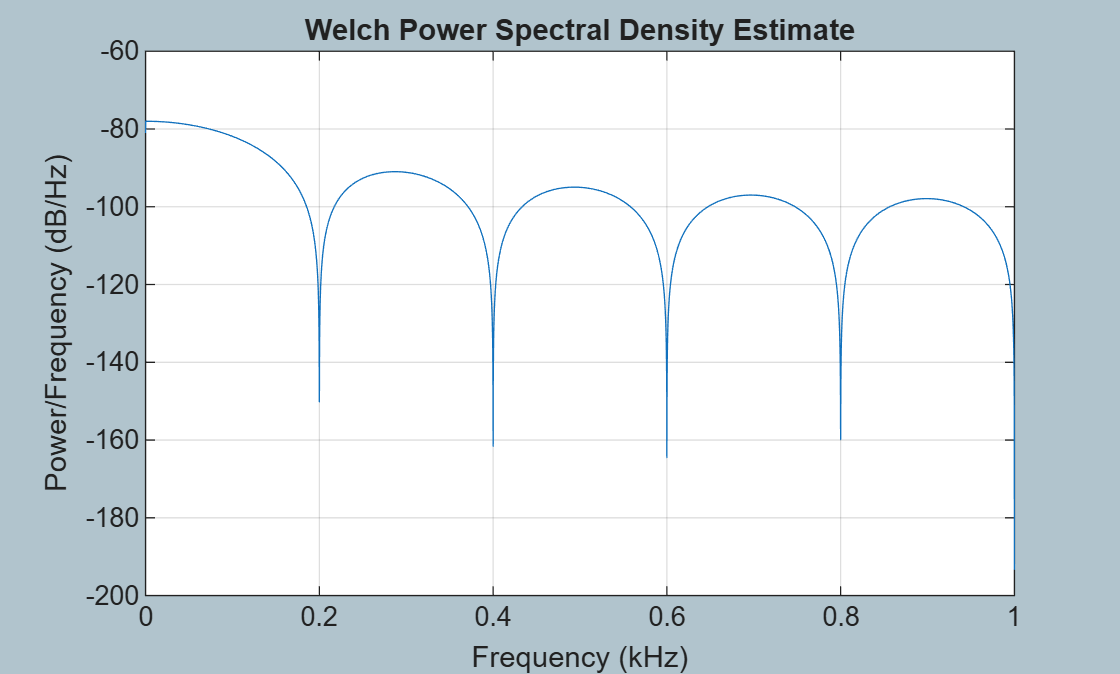

figure;
    pwelch(y_imp,[],[],[],gdsp_basic.Fs_hz)

#### OBSERVATIONS:

- Let:   $W=\mathrm{Pulse}\;\mathrm{width}\;\mathrm{in}\;\mathrm{seconds}$

- Note all of the "inverted" spikes occurring at frequencies $f=k\ldotp \left(\frac{1}{W}\right)\;\left\lbrack \mathrm{Hz}\right\rbrack$.

- These will present as GHOST resonances when you compute FRFs.

- So ? - So it's important you understand the excitation bandwidth that an IMPULSE force provides

## PART_02:  White Gaussian Noise(WGN) excitation

Define the WGN signal

- see DOC [`wgn()`](https://au.mathworks.com/help/releases/R2024b/comm/ref/wgn.html)

rng(0)

% y_WGN = 1 * wgn(length(t_col),1, 10,1, 0, 'linear');
y_WGN = 1 * randn(length(t_col),1);

### Plot the WGN signal:

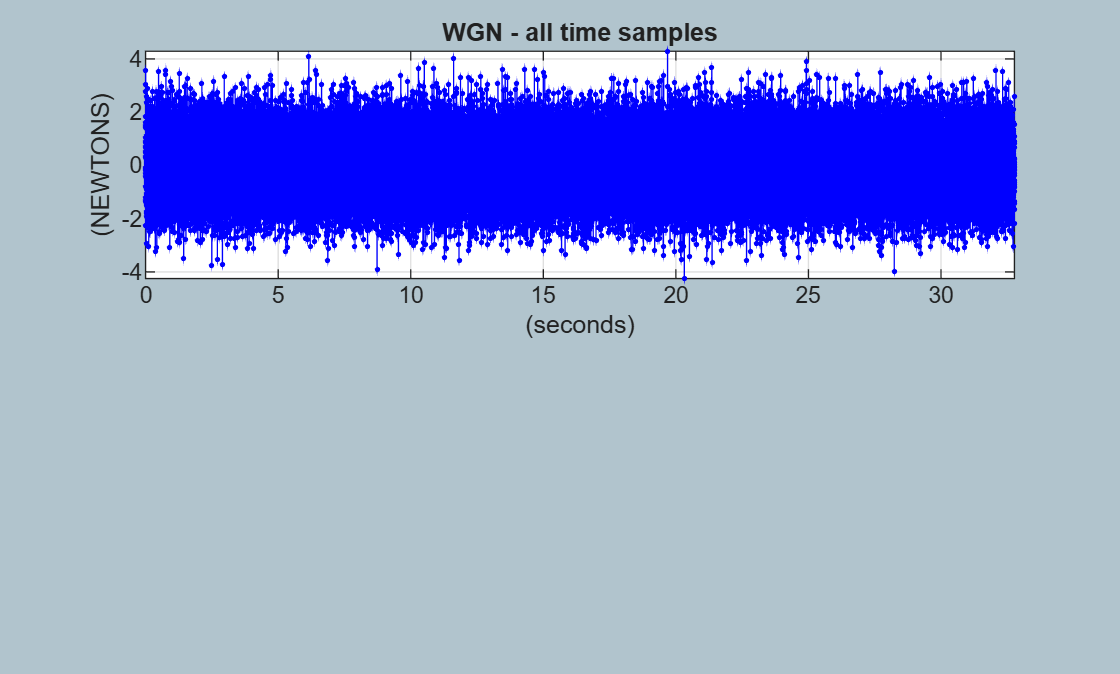

figure;
    subplot(2,1,1);
        stairs(t_col, y_WGN, "-b.");
            grid on
            xlabel("(seconds)"); ylabel("(NEWTONS)");
            title("WGN - all time samples")
            axis tight

### Compute the FFT

yfft            = fft(y_WGN);

yfft_dB         = 20*log10( abs(yfft)  );

DC_gain_dB      = yfft_dB(1);

### Plot the FFT spectrum:

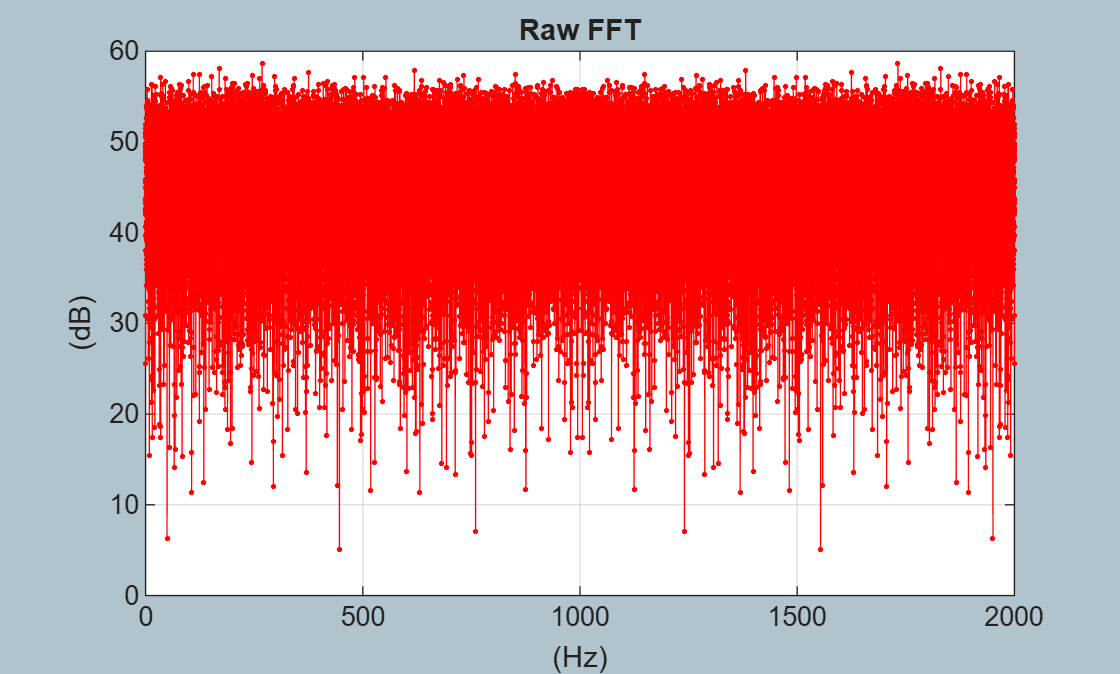

figure;
    plot(f_hz_col, 20*log10(abs(yfft)), "-r.");
        grid on
        xlabel("(Hz)"); ylabel("(dB)");
        title("Raw FFT")

### Plot The Power Spectral Density (PSD)

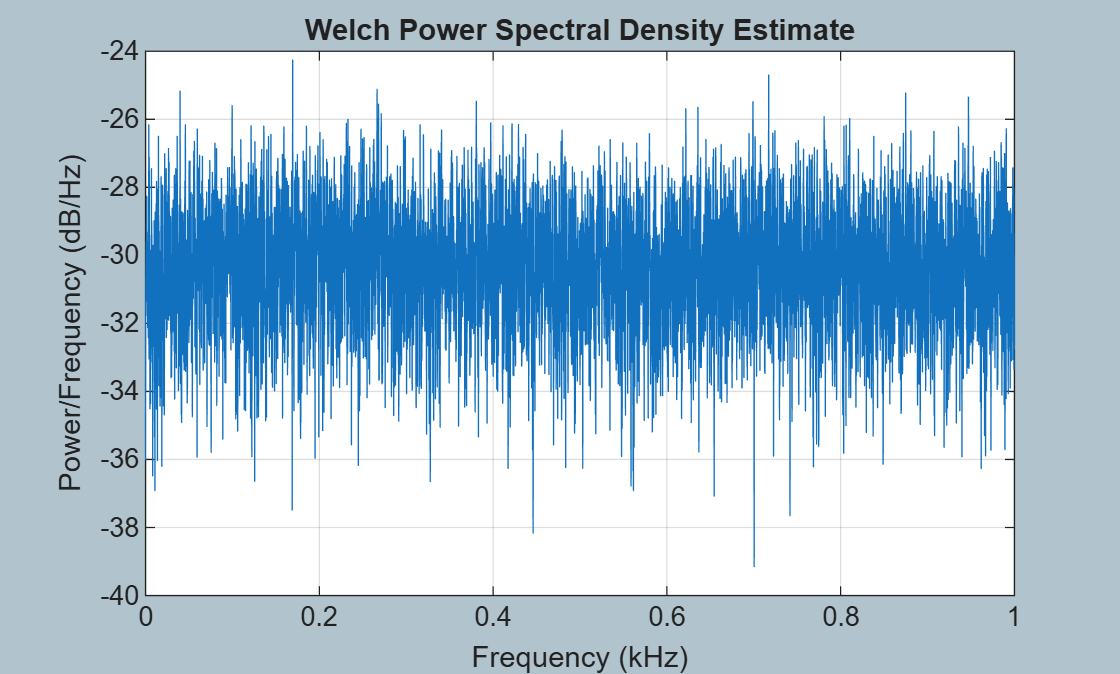

figure;
    pwelch(y_WGN,[],[],[],gdsp_basic.Fs_hz)

## PART_03:  Band Limited Noise (BLN) excitation

F_pass_Hz = 0.2*gdsp_basic.Fs_hz;
F_stop_Hz = 0.3*gdsp_basic.Fs_hz;
MAG_y     = 200;    

obj_BLN   = bh_Modal.CLS_BLN(F_pass_Hz, F_stop_Hz, gdsp_basic.Fs_hz);

obj_BLN = obj_BLN.create_sig( length(t_col),  MAG_y );

### Plot the BLN signal:

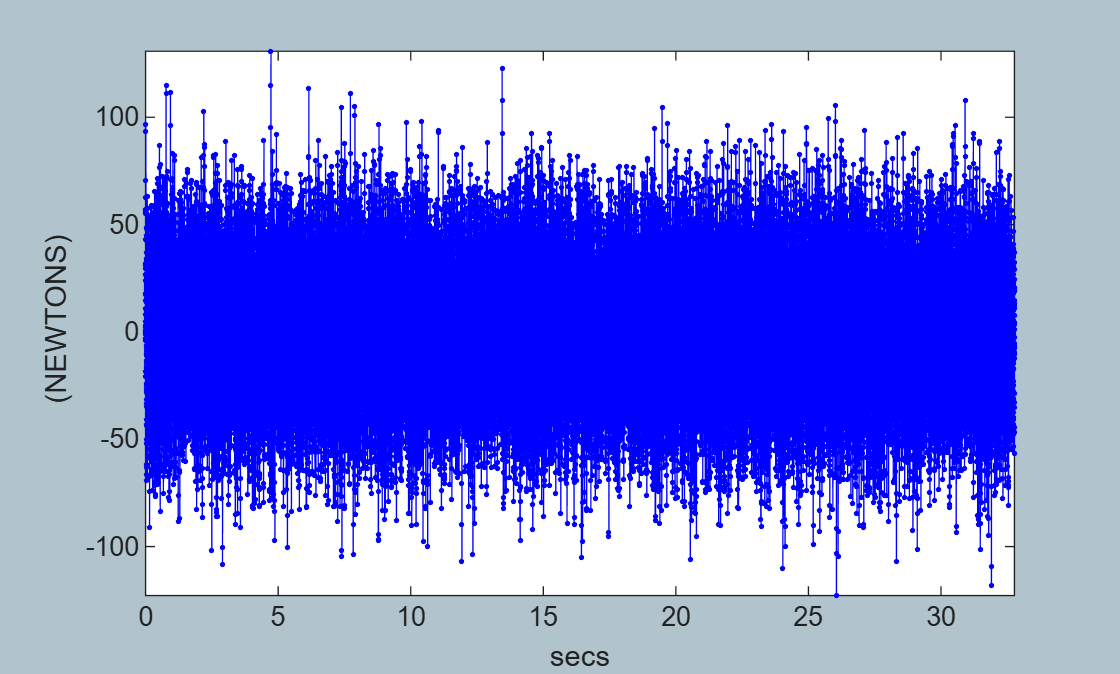

figure;
    obj_BLN.plot()

### Compute the FFT

yfft            = fft(obj_BLN.y_col);

yfft_dB         = 20*log10( abs(yfft)  );

DC_gain_dB      = yfft_dB(1);

### Plot the FFT spectrum:

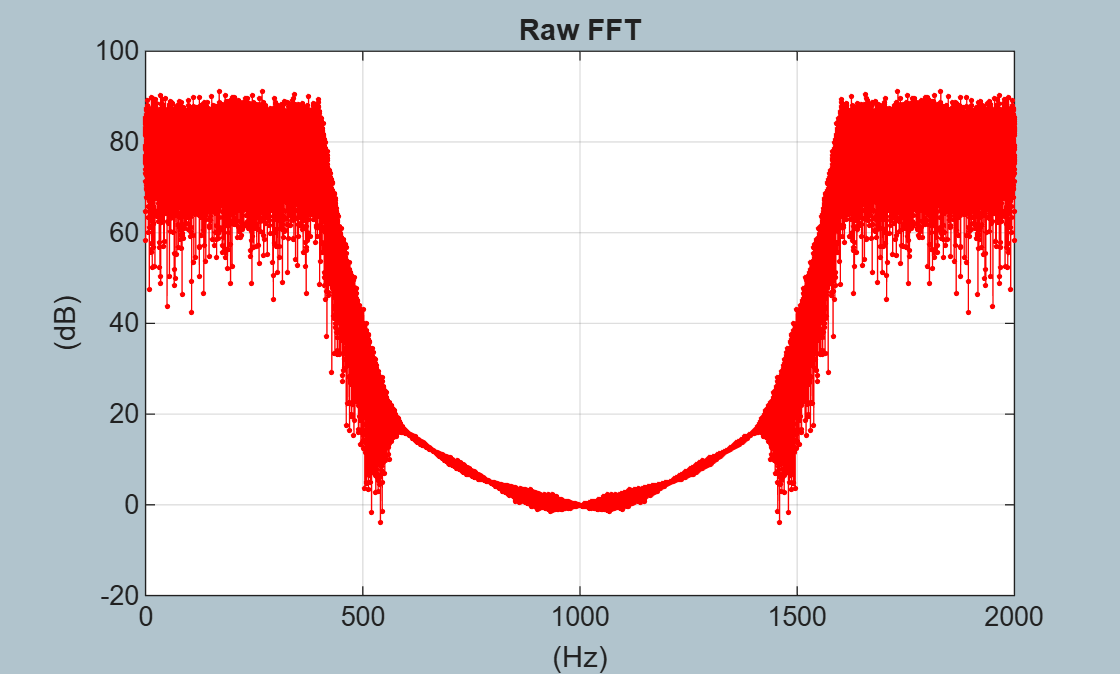

figure;
    plot(f_hz_col, 20*log10(abs(yfft)), "-r.");
        grid on
        xlabel("(Hz)"); ylabel("(dB)");
        title("Raw FFT")

### Plot The Power Spectral Density (PSD)

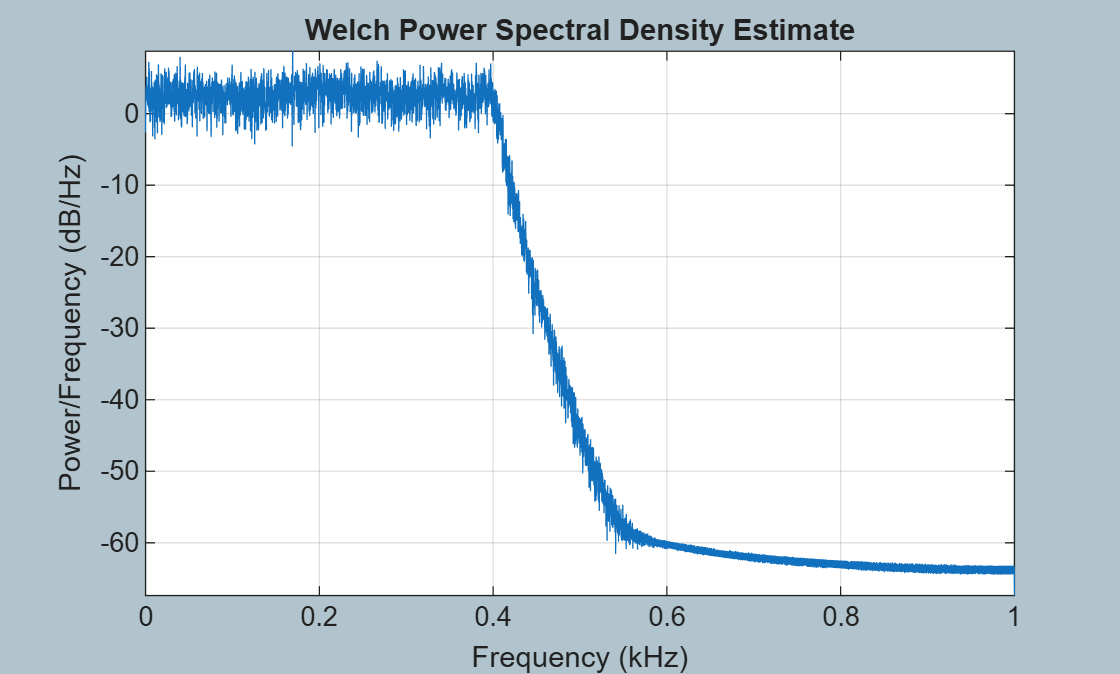

figure;
   obj_BLN.plot_psd();